# X Airline Fuel Estimation and Analysis V2

َAlireza Ghaderi 

p30planets@gmail.com

ghaderi@alumsharif.org

[https://www.linkedin.com/in/alireza787b/](https://www.linkedin.com/in/alireza787b/)

Script for importing data from the following spreadsheet:

19-Jul-2022 03:05:57

## Set up the Import Options and import the data

clear;
opts = spreadsheetImportOptions("NumVariables", 39);
apt = import_apt('../apt.xlsx')

apt = 26×5 table
           iata     icao     elev     lat       long 
           ____    ______    ____    ______    ______

    KIH    KIH     "OIBK"      99    26.527    53.978
    IFN    IFN     "OIFM"    5059     32.75    51.863
    MHD    MHD     "OIMM"    3266    36.233    59.645
    HDM    HDM     "OIHH"    5771     34.87     48.55
    SYZ    SYZ     "OISS"    4927     29.54    52.588
    THR    THR     "OIII"    3965    35.688    51.315
    OMH    OMH     "OITR"    4342    37.672    45.068
    ABD    ABD     "OIAA"       8    30.372    48.228
    AWZ    AWZ     "OIAW"      65    31.337     48.76
    GSM    GSM     "OIKQ"      45    26.752    5

save ../apt apt
load ../apt.mat

% Specify sheet and range
opts.Sheet = "Sheet1";
opts.DataRange = "A2:AM5115";

% Specify column names and types
opts.VariableNames = ["ACType", "ACReg", "FlightDateM", "FlightNo", "Origin", "Destination", "Airborn", "OffBlock", "TouchDown", "OnBlock", "BaggageKG", "BaggagePD", "AdultCount", "InfantCount", "ChildCount", "FlightTime", "BlockTime", "SitaFlightTime", "RemainingFuelKG", "RemainingFuelLt", "RemainingFuelPD", "UpliftFuelKG", "UpliftFuelLT", "UpliftFuelPD", "ArrFuelKG", "ArrFuelLT", "ArrFuelPD", "DiffFuelKG", "DiffFuelLT", "DiffFuelPD", "RampFuelKG", "RampFuelLT", "RampFuelPD", "SitaFuelKG", "SitaFuelLT", "SitaFuelPD", "TaxiFuelKG", "TaxiFuelLT", "TaxiFuelPD"];
opts.VariableTypes = ["categorical", "categorical", "datetime", "string", "categorical", "categorical", "datetime", "datetime", "datetime", "datetime", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double"];

% Specify file level properties
opts.ImportErrorRule = "omitrow";
opts.MissingRule = "omitrow";

% Specify variable properties
opts = setvaropts(opts, "FlightNo", "WhitespaceRule", "preserve");
opts = setvaropts(opts, ["ACType", "ACReg", "FlightNo", "Origin", "Destination"], "EmptyFieldRule", "auto");
opts = setvaropts(opts, "FlightDateM", "InputFormat", "");
opts = setvaropts(opts, "Airborn", "InputFormat", "");
opts = setvaropts(opts, "OffBlock", "InputFormat", "");
opts = setvaropts(opts, "TouchDown", "InputFormat", "");
opts = setvaropts(opts, "OnBlock", "InputFormat", "");
opts = setvaropts(opts, ["BaggageKG", "BaggagePD", "AdultCount", "InfantCount", "ChildCount", "FlightTime", "BlockTime", "SitaFlightTime", "RemainingFuelKG", "RemainingFuelLt", "RemainingFuelPD", "UpliftFuelKG", "UpliftFuelLT", "UpliftFuelPD", "ArrFuelKG", "ArrFuelLT", "ArrFuelPD", "DiffFuelKG", "DiffFuelLT", "DiffFuelPD", "RampFuelKG", "RampFuelLT", "RampFuelPD", "SitaFuelKG", "SitaFuelLT", "SitaFuelPD", "TaxiFuelKG", "TaxiFuelLT", "TaxiFuelPD"], "TreatAsMissing", '');

% Import the data
FuelAndTime1 = readtable("FuelAndTime (1).xlsx", opts, "UseExcel", false);
data = FuelAndTime1

data = 9×39 table
    ACType    ACReg     FlightDateM    FlightNo    Origin    Destination          Airborn                 OffBlock               TouchDown                OnBlock           BaggageKG    BaggagePD    AdultCount    InfantCount    ChildCount    FlightTime    BlockTime    SitaFlightTime    RemainingFuelKG    RemainingFuelLt    RemainingFuelPD    UpliftFuelKG    UpliftFuelLT    UpliftFuelPD    ArrFuelKG    ArrFuelLT    ArrFuelPD    DiffFuelKG    DiffFuelLT    DiffFuelPD    

**PreProcess**

**Aircraft Type:**

type = "MD";
if type ~= "0" 
    idx = (data.ACType == type);
    data = data(idx,:);
end
data

data = 7×39 table
    ACType    ACReg     FlightDateM    FlightNo    Origin    Destination          Airborn                 OffBlock               TouchDown                OnBlock           BaggageKG    BaggagePD    AdultCount    InfantCount    ChildCount    FlightTime    BlockTime    SitaFlightTime    RemainingFuelKG    RemainingFuelLt    RemainingFuelPD    UpliftFuelKG    UpliftFuelLT    UpliftFuelPD    ArrFuelKG    ArrFuelLT    ArrFuelPD    DiffFuelKG    DiffFuelLT    DiffFuelPD    

**Route:**

apt1 = "0";
apt2 = "0";
if apt1 == '0' && apt2 ~= '0'
    idx =  (data.Origin == apt2 | data.Destination == apt2) ;
    data = data(idx,:);
elseif apt2 == '0' && apt1 ~= '0'
    idx =  (data.Origin == apt1 | data.Destination == apt1) ;
    data = data(idx,:);
elseif apt2 ~= '0' && apt1 ~= '0'
    idx = ((data.Origin == apt1 | data.Origin == apt2) & (data.Destination == apt1 | data.Destination == apt2) ) ;
    data = data(idx,:)
end

**Register:**

reg = "0";

if reg ~= "0" 
    reg = strcat('EP-',reg);
    idx = (data.ACReg == reg);
    data = data(idx,:);
end
data

data = 7×39 table
    ACType    ACReg     FlightDateM    FlightNo    Origin    Destination          Airborn                 OffBlock               TouchDown                OnBlock           BaggageKG    BaggagePD    AdultCount    InfantCount    ChildCount    FlightTime    BlockTime    SitaFlightTime    RemainingFuelKG    RemainingFuelLt    RemainingFuelPD    UpliftFuelKG    UpliftFuelLT    UpliftFuelPD    ArrFuelKG    ArrFuelLT    ArrFuelPD    DiffFuelKG    DiffFuelLT    DiffFuelPD    

**Add Secondary Data**

adultKG = 100;
childKG = 45;
infantKG = 13;
data.distance = getDistance(string(data.Origin),string(data.Destination));
data.fieldElev1 = getElev(string(data.Origin));
data.fieldElev2 = getElev(string(data.Destination));
data.dayOfYear = day(data.FlightDateM,"dayofyear");
data.hourOfDay = data.Airborn.Hour;
data.payloadKg = data.AdultCount * adultKG + data.ChildCount*childKG + data.InfantCount*infantKG + data.BaggageKG;
data.totalWeightKg = data.payloadKg + data.RampFuelKG;
data.usedFuelKg = data.RampFuelKG - data.ArrFuelKG;

**Outlier**

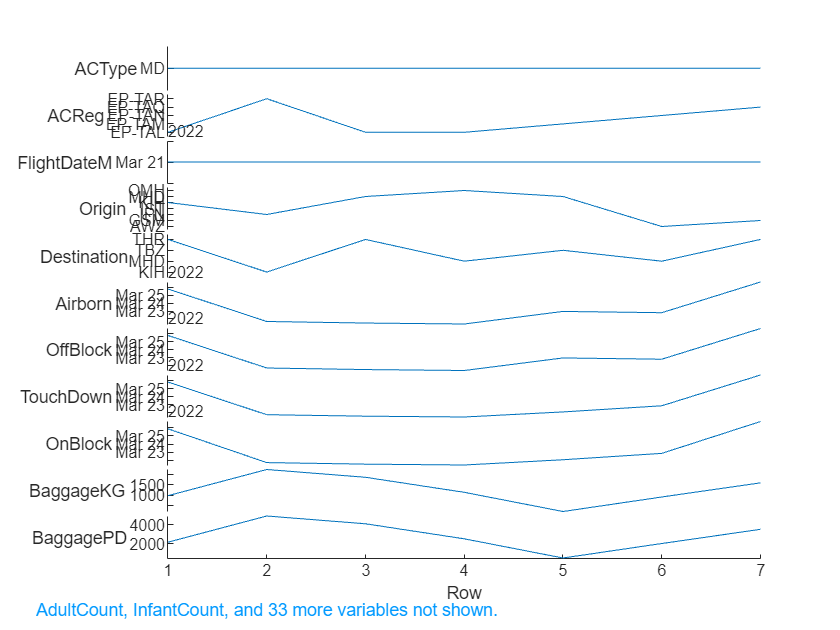



stackedplot(data)

save ../fullData data;
load ../fullData

**Data Predict Template:**

**SVM Model Data Preparation**

 trained2 = true;
 
BlockTime = 100;
FlightTime = 80;
dayofYear = 60;
hourofDay = 40;
PayloadKG = 10000;
TotalKG = 22000;
if trained2 == true 
load svm3Full.mat 
  varNames = ["BlockTime","FlightTime","dayOfYear","distance","fieldElev1","fieldElev2",...
     "hourOfDay","payloadKg","totalWeightKg"];
 varTypes = ["double","double","double","double","double","double","double","double","double"];
 inT = table('Size',size(varNames),'VariableTypes',varTypes,'VariableNames',varNames);
  inT(1,:) = array2table([BlockTime FlightTime dayofYear Distance fieldElev1 fieldElev2 hourofDay PayloadKG TotalKG]);
  fuelPredict = trainedModel.predictFcn(inT)
end

fuelPredict = 4.1875e+03

## Clear temporary variables

clear opts